# **An introduction to Matlab for dynamic modeling**

## **1: Interactive Calculations**

EX1.1 Reasons for invalid names

% cell.maximum.size: cannot contain '.' in variable name
% 4min: a variable name cannot start with a number. Must start with a
% letter.
% site#7: the '#' symbol cannot be used

Non-exercises

x = 5; y = 2; z1 = x*y, z2 = x/y, z3 = x^y

z1 = 10

z2 = 2.5000

z3 = 25


X = ones(4,2)

X =      1     1
     1     1
     1     1
     1     1


X

X =      1     1
     1     1
     1     1
     1     1


EX1.2

max(2^5/(2^5-1), (1-2/(2^5)))

ans = 1.0323

sin(pi/6), (cos(pi/8))^2

ans = 0.5000

ans = 0.8536

2^5/(2^5-1) + 4*sin(pi/6)

ans = 3.0323

EX1.3

% Ex1.3
help hist % help functionname

 hist  Histogram.
    hist is not recommended. Use HISTOGRAM or HISTCOUNTS instead.
  
    N = hist(Y) bins the elements of Y into 10 equally spaced containers
    and returns the number of elements in each container.  If Y is a
    matrix, hist works down the columns.
 
    N = hist(C) returns the category counts for the categorical array C.
    For a categorical matrix, hist works down the columns of Y and returns
    a matrix of counts with one column for each column of Y and one row for
    each category.
 
    N = hist(Y,M), where M is a scalar, uses M bins.
 
    N = hist(Y,X), where X is a vector, returns the distribution of Y among
    bins with centers specified by X. The first bin includes data between
    -inf and the first center and the last bin includes data between the
    last bin and inf. Note: Use HISTC if it is more natural to specif

doc hist
y = randn(5000, 1)

y =    -1.9184
   -0.1311
   -0.7686
    2.3900
    0.0772
    0.3756
    0.3956
   -0.1125
   -1.8290
    2.0915


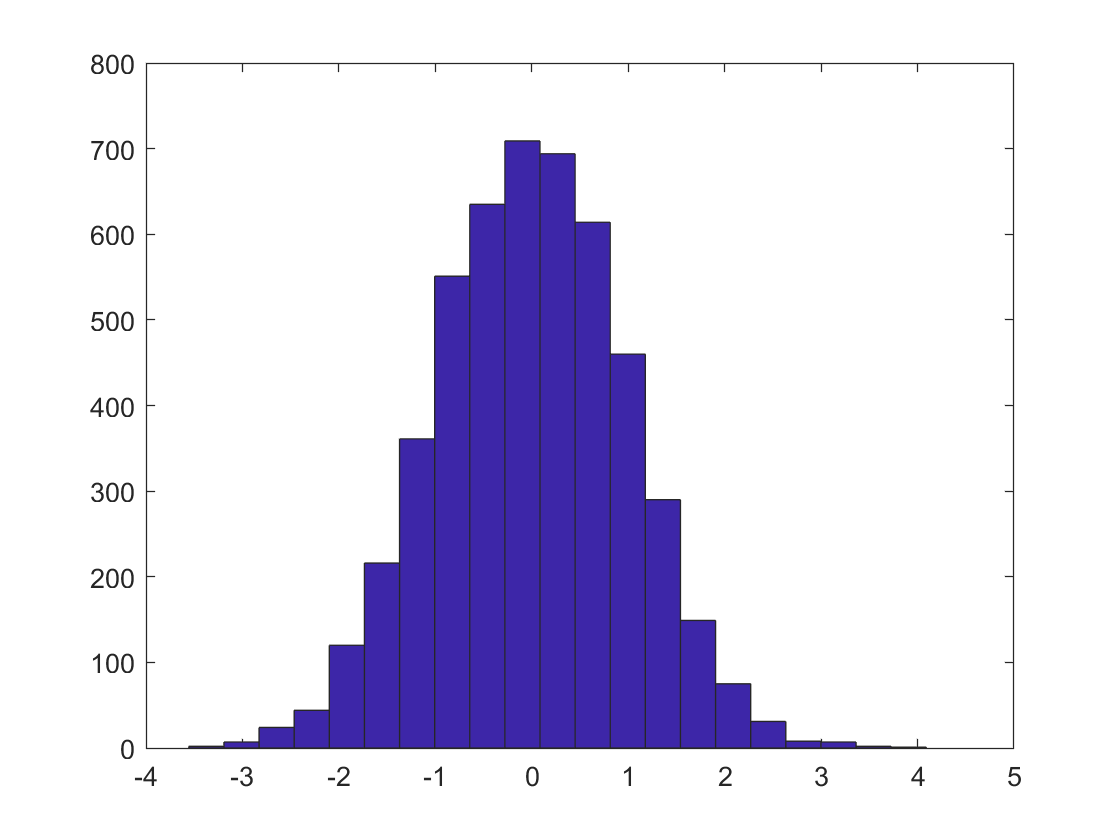

hist(y, 21)

## 2: An Interactive Session: Linear Regressions

Light = [20 20 20 20 21 24 44 60 90 94 101]

Light =     20    20    20    20    21    24    44    60    90    94   101


rmax = [1.73 1.65 2.02 1.89 2.61 1.36 2.37 2.08 2.69 2.32 3.67]

rmax =     1.7300    1.6500    2.0200    1.8900    2.6100    1.3600    2.3700    2.0800    2.6900    2.3200    3.6700


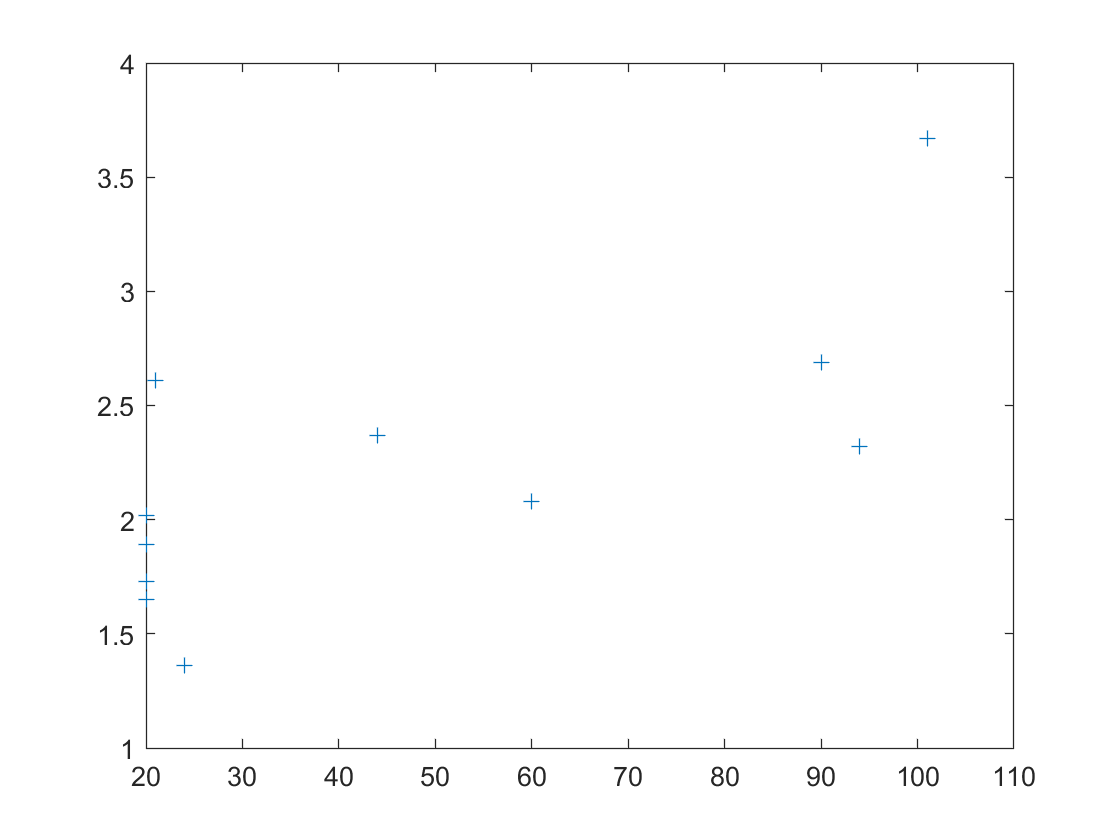

plot(Light, rmax, '+')

C = polyfit(Light, rmax, 1) % calculates linear regression coefficients

C =     0.0136    1.5810


C

C =     0.0136    1.5810


min(Light), max(Light)

ans = 20

ans = 101

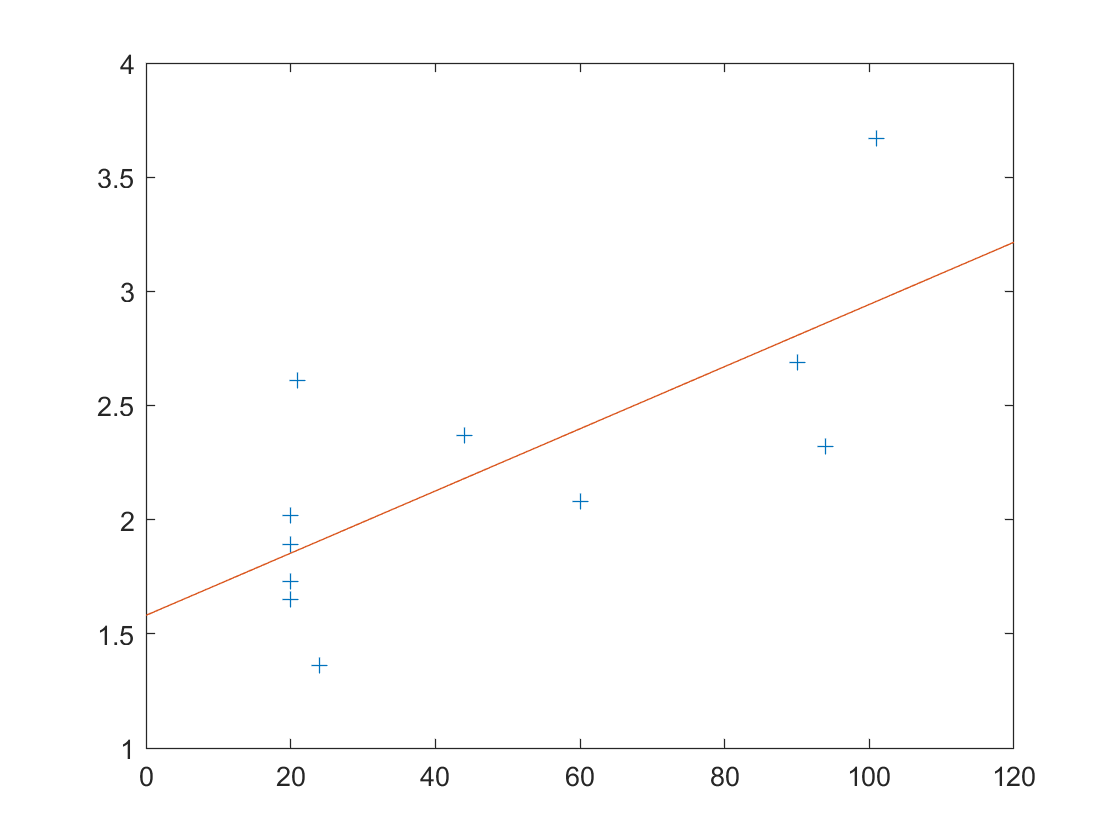

xvals = 0:120;
yhat = polyval(C, xvals); % uses the coefficients in C to calculate the regression line at the values in xvals.
plot(Light, rmax, '+', xvals, yhat)

## 3: M-files and Data Files

EX3.1

% Modifying Intro2.m
% 3.1.1

%Load data from file
X=load('ChlorellaGrowth.txt');

%Define vectors by slicing data. i.e. Extracting data.
Light=X(:,1); rmax=X(:,2); 

%Repeat computations from Intro1
C=polyfit(log(Light),rmax,1)

C =     0.6167   -0.0109


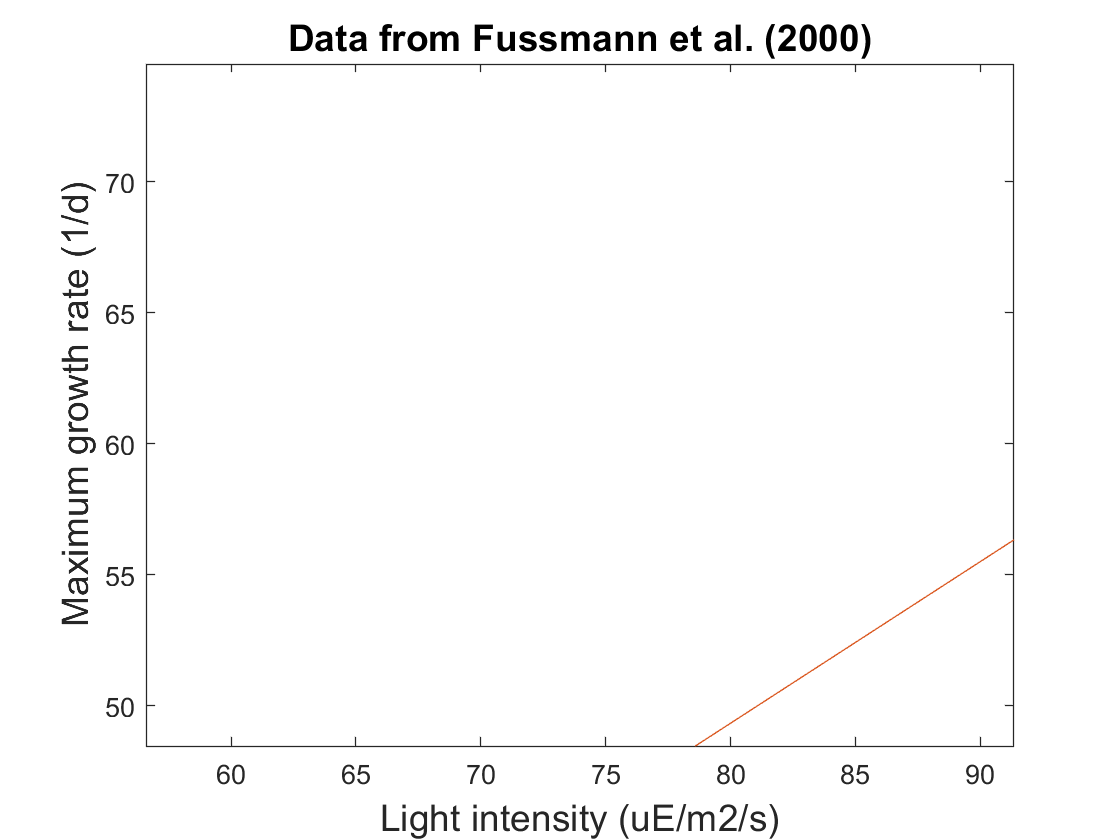

xvals=0:120; 
yhat=polyval(C,xvals);
plot(Light,log(rmax),'+',xvals,yhat);

%Annotate plot with labels, title and text
xlabel('Light intensity (uE/m2/s)','Fontsize',14); 
ylabel('Maximum growth rate (1/d)','Fontsize',14);
title('Data from Fussmann et al. (2000)','FontSize',14);
text(30,3.5,'y= 1.581+ 0.0136*x','Fontsize',14);

Second task.

% Modifying Intro2.m
% 3.1.1

%Load data from file
X=load('ChlorellaGrowth.txt');

%Define vectors by slicing data. i.e. Extracting data.
Light=X(:,1); rmax=X(:,2); 

%Repeat computations from Intro1
C1=polyfit(Light,rmax,1)

C1 =     0.0136    1.5810


C2=polyfit(Light,rmax,2)

C2 =     0.0002   -0.0136    2.0939


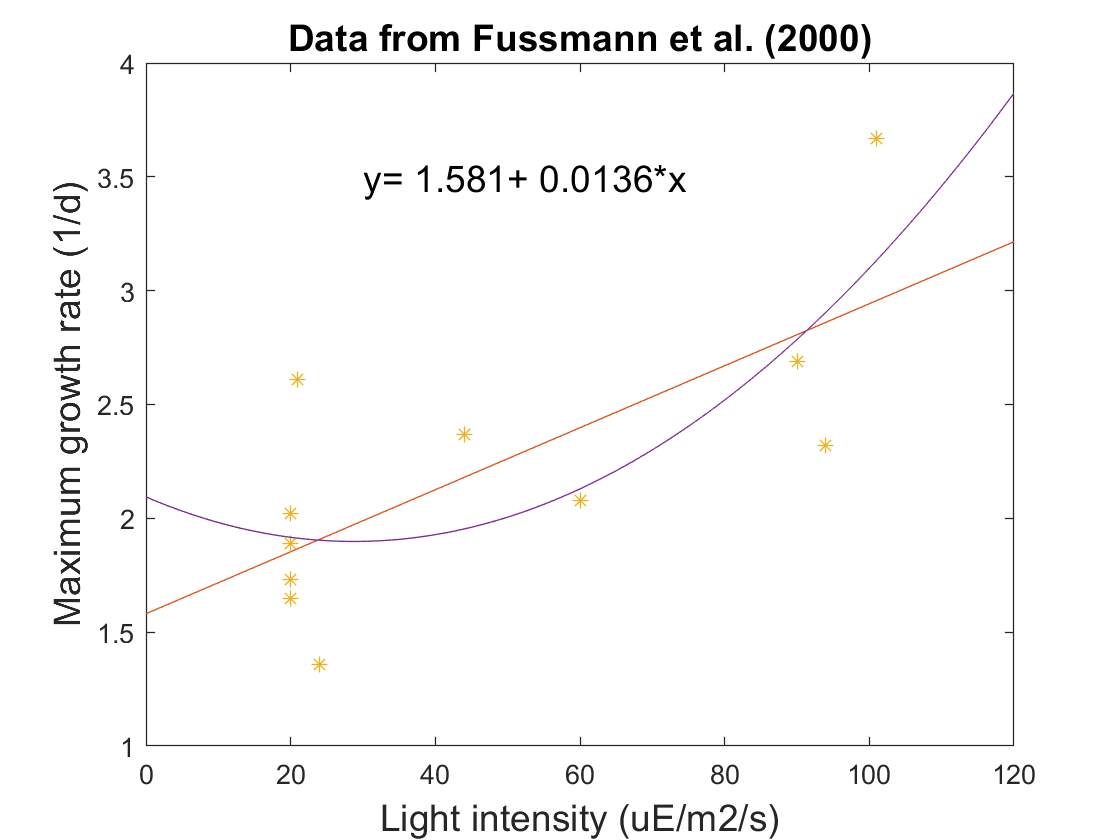

xvals=0:120; 
yhat1=polyval(C1,xvals); yhat2=polyval(C2,xvals);
plot(Light,rmax,'+',xvals,yhat1,Light,rmax,'*',xvals,yhat2);

%Annotate plot with labels, title and text
xlabel('Light intensity (uE/m2/s)','Fontsize',14); 
ylabel('Maximum growth rate (1/d)','Fontsize',14);
title('Data from Fussmann et al. (2000)','FontSize',14);
text(30,3.5,'y= 1.581+ 0.0136*x','Fontsize',14);

EX3.2

m = 2
b = 2.5
x = 1:10
plot(x,m*x+b)

EX3.3

%Load data from file
X=load('ChlorellaGrowth.txt');

%Define vectors by slicing data. i.e. Extracting data.
subplot(2,1,1)
Light=X(:,1); rmax=X(:,2); 

%Repeat computations from Intro1
C1=polyfit(Light,rmax,1)
xvals=0:120; 
yhat1=polyval(C1,xvals);

subplot(2,1,1)
C1=polyfit(log(Light),log(rmax),1)
yhat2=polyval(C2,xvals);

plot(Light,rmax,'+',xvals,yhat1, log(Light),log(rmax),'*',xvals,yhat2);
%Annotate plot with labels, title and text
xlabel('Light intensity (uE/m2/s)','Fontsize',14); 
ylabel('Maximum growth rate (1/d)','Fontsize',14);
title('Data from Fussmann et al. (2000)','FontSize',14);
text(30,3.5,'y= 1.581+ 0.0136*x','Fontsize',14);

EX3.4

% An "axis" command after the "plot" change scale.

%Load data from file
X=load('ChlorellaGrowth.txt');

%Define vectors by slicing data. i.e. Extracting data.
Light=X(:,1); rmax=X(:,2); 

%Repeat computations from Intro1
C=polyfit(Light,rmax,1)
xvals=0:120;
yhat=polyval(C,xvals);
%axis('equal') % forces Matlab to use the same scale on both axes
plot(Light,rmax,'+',xvals,yhat);
axis([15 105 1 4])
plot(Light,rmax,'+',xvals,yhat);

%Annotate plot with labels, title and text
xlabel('Light intensity (uE/m2/s)','Fontsize',14); 
ylabel('Maximum growth rate (1/d)','Fontsize',14);
title('Data from Fussmann et al. (2000)','FontSize',14);
text(30,3.5,'y= 1.581+ 0.0136*x','Fontsize',14);

## 4: Vectors

EX4.1

v = 1:4:13
v = linspace(1,13,4)

EX4.2

sum(0.5.^[0:1:10]), 1/(1-0.5) % n=10
sum(0.5.^[0:1:50]), 1/(1-0.5) % n=50

EX4.3

initialsize = [1,3,5,7,9,11]
c = initialsize(1:3)

## 5: Matrices

EX5.1

M = rand(5,5)
M1 = M(2,:)
M2 = M(:,2)
M3 = M(2:4,2:4)

M(1,:) = linspace(2,14,5)

## 6: Iteration ("Looping")

EX6.1

M = zeros(30,1) % not necessary
A = zeros(30,1) % not necessary
for n=1:30
    M(n)=400*((1.1)^n);
    A(n)=120*((1.2)^n);
end

r =size(M);
xvals=(1:r)-1;
plot(xvals, log(M), xvals, log(A));

EX6.2

M = zeros(5,5)
for i=1:4
    M(1,i) = i
    M(i+1,i) = i/10
end

EX6.3

t = 1:30
nt = (400*((1.1).^t))
mt = 120*((1.2).^t)

EX6.4

7: Branching

EX7.1

for n=0:29
    r = rand(1)
    if(r > 0.35)
        M(n+1)=1.1*(400*((1.1)^n));
        A(n+1)=1.2*(120*((1.2)^n));
    else
        M(n+1)=0.9*(400*((1.1)^n));
        A(n+1)=0.8*(120*((1.2)^n));
    end
end
M
A
r =size(M)
xvals=(1:r)-1;
%plot(xvals, log(M), xvals, log(A));
plot(xvals, M, xvals, A);

8: Matrix Computations

EX8.1

Find right eigenvector

A = [1 5 0; 6 4 0; 0 1 2]
L = eig(A) % find all the eigenvalues of A

j = find(abs(L)==max(abs(L)))
L1 = L(j)
ndom = length(L1) % Extract the dominant eigen value

% find the corresponding (right) eigenvector, scaled as in Section 8.
[W,D] = eig(A)
L = diag(D)
j = find(abs(L)==max(abs(L)))
L1 = L(j)
w=W(:,j)

Find the dominant left eigenvector (by repeating the process on tranpose of A)

A = [1 5 0; 6 4 0; 0 1 2]
B = transpose(A)
L = eig(B) % find all the eigenvalues of A

j = find(abs(L)==max(abs(L)))
L1 = L(j)
ndom = length(L1) % Extract the dominant eigen value

% find the corresponding (left) eigenvector, scaled as in Section 8.
[V,D] = eig(B)
L = diag(D)
j = find(abs(L)==max(abs(L)))
L1 = L(j)
v =W(:,j)

EX8.2

% The matrix M and the dominant eigenvalue lambda is correct
% However, v and w are wrong for some reason, and will fix later.

Creating the transition matrix

M = zeros(7,7);
n = 7
p = [0.3, 0.4, 0.5, 0.6, 0.6, 0.7]

for i=1:n
    for j=1:n
        if(i==1 & j==7)
            M(i,j)= 12;
        elseif(i==7 & j==7)
            M(i,j)= 0.9;
        elseif(i==j+1)
            M(i,j) = p(i-1);
        else
            M(i,j) = 0;
        end
    end
end
M

Find right eigenvector

L = eig(M); % find all the eigenvalues of M
j = find(abs(L)==max(abs(L)))
L1 = L(j)
ndom = length(L1) % Extract the dominant eigen value

% find the corresponding (right) eigenvector, scaled as in Section 8.
[W,D] = eig(M)
L = diag(D)
j = find(abs(L)==max(abs(L)))
lambda = L(j)
w = W(:,j)

Find the dominant left eigenvector (by repeating the process on tranpose of M)

B = transpose(M);
L2 = eig(B) % find all the eigenvalues of A

j = find(abs(L2)==max(abs(L2)))
lambda = L2(j)
ndom = length(L2) % Extract the dominant eigen value

% find the corresponding (left) eigenvector, scaled as in Section 8.
[V,D] = eig(B)
L2 = diag(D)
j = find(abs(L2)==max(abs(L2)))
L1 = L2(j)
v =V(:,j)
n = length(v)


% Some extra info introduced in the section.
vdotw = dot(v,w)
for i=1:n; 
    for j=1:n;
        s(i,j) = v(i)*w(j)/vdotw;
    end
end
e = (s.*M)/lambda


9: Creating New Functions

9.1 Simple Functions

9.2 Functions with Multiple Arguments or Returns

EX9.1

EX9.2

EX9.3

10: A Simulation Project

EX10.1

EX10.2

11: Coin Tossing and Markov Chains

EX11.1

EX11.2

EX11.3

EX11.4

EX11.5

EX11.6

EX11.7